# Handle Errors After All Functions Run in the Background

This example shows how to use `afterAll` to handle errors from functions that run in the background.

When you call `afterAll` on `Future` objects that result in errors, by default, `afterAll` also errors. If you want to handle any errors in the preceding futures, for example, when you have a user interface that you want to update, you can use the `PassFuture` argument. When you set `PassFuture` to `true`, MATLAB passes the array of `Future` objects to the callback function. You can interact with the individual elements of the `Future` array, process the outputs, and handle any possible errors.

Send computations to the background using `parfeval`. Some of these computations deliberately result in errors.

N = 10;
F(1:N) = parallel.FevalFuture;
for idx = 1:2:N
    F(idx) = parfeval(backgroundPool,@rand,1,1);
end

for idx = 2:2:N
    F(idx) = parfeval(backgroundPool,@rand,1,0.1);
end

 If any of the elements in the preceding futures encounters an error, `afterAll` finishes with an error. In the code below, `afterAll` errors. Use the `Error` property of the `afterAll` future `a` to view the error.

a  = afterAll(F,@mean,1);
wait(a)
a.Error

To handle the elements in the preceding futures that have errors, write a callback function that takes in the future array as an input argument. The `displayRunSummary` helper function determine which futures completed successfully using the `Error` property and fetches their outputs. It then calculates the mean of the completed runs and displays this information in a user interface, including a table showing the completion status of each computation.

a2 = afterAll(F,@displayRunSummary,0,PassFuture=true);

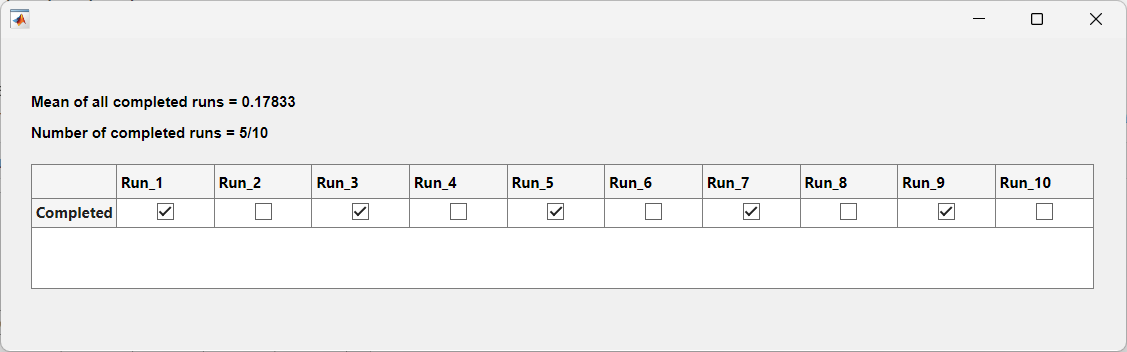

function displayRunSummary(F)
N = numel(F);
output = zeros(N,1);
for idx = 1:N
    f = F(idx);
    field = strcat("Run_",num2str(idx));
    results.(field) = isempty(f.Error);
    if isempty(f.Error)
        output(idx) = fetchOutputs(f);
    end
end
meanAll = mean(output,"omitmissing");

fig = uifigure('Position',[100 100 900 250]);

runText = strcat("Number of completed runs = ", ...
    num2str(nnz(output)),"/",num2str(numel(output)));
uilabel(fig,Text=runText,FontWeight="bold",Position=[25 125 700 100]);

meanText = strcat("Mean of all completed runs = ",num2str(meanAll));
uilabel(fig,Text=meanText,FontWeight="bold",Position=[25 150 700 100]);

t = struct2table(results);
t.Properties.RowNames = "Completed";
uitable(fig,Position=[25 50 850 100],Data=t);
end

*Copyright 2024 The MathWorks, Inc.*